# Discrete time models and their usage in MATLAB

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of discrete time models and how these can be handled in MATLAB. 

Often discrete models can be treated using Z-transforms which MATLAB handles formally using tools in the control toolbox. This file looks at the basic definition and usage of such discrete models.

It is noted that much of the functionality is equivalent to the use of continuous time models and thus is implicitly covered, with very minor changes (e.g. replace *G(s)* object by *G(z)*), in earlier files such as: ***closed_loop_compare_multiple_compensators.mlx, *** ***transferfunctions_and_poles.mlx ***and ***step_responses_with_matlab.mlx.***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Forming discrete time models from continuous models

- Forming discrete time models directly

- Illustration of basic usage of discrete models with control toolbox files

## 1.Technical and mathematical background

This file does not discuss details such as the zero-order-hold and sampler in detail.

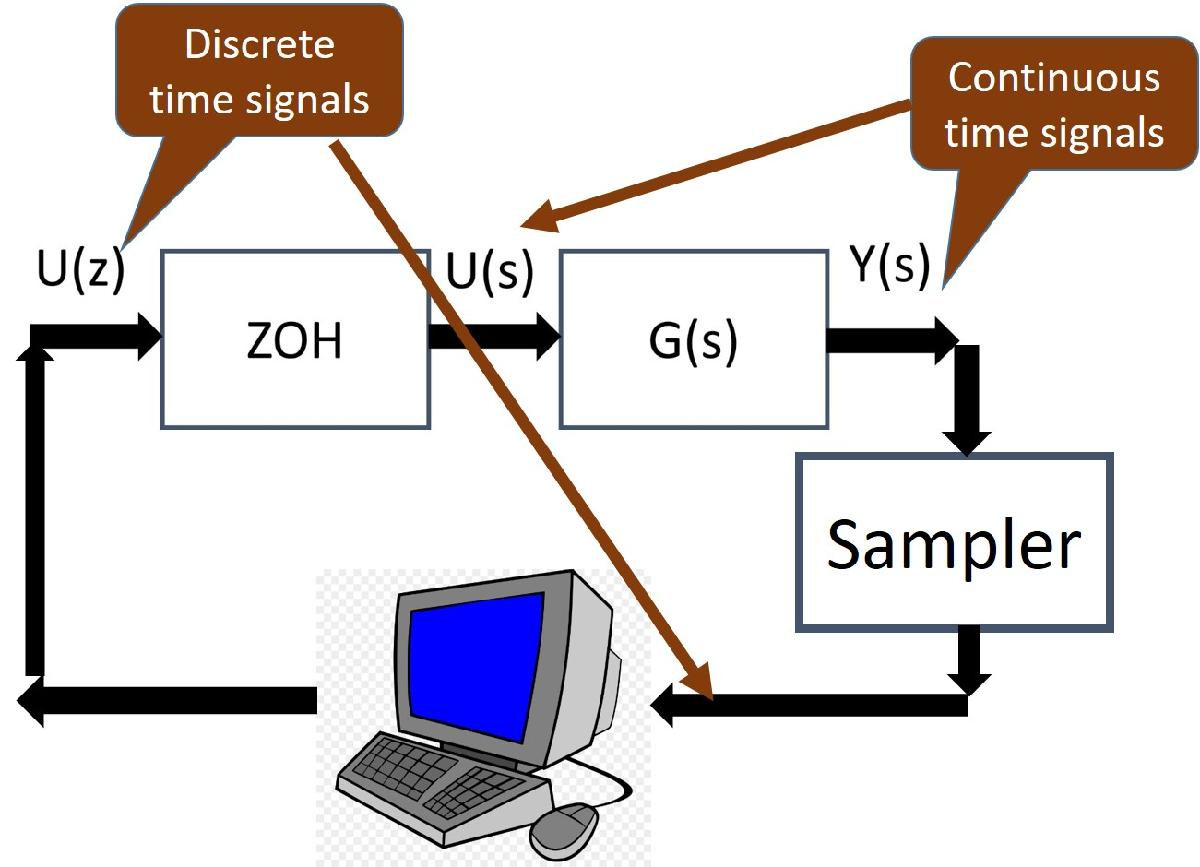

- The discretised system model *G(z)* includes the ZOH (zero-order-hold) and sampler.

- The compensator *M(z)* works entirely in discrete time (e.g. represented by the computer above).

An  z-transform model could be represented as:


$$\left(1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots \right)y\left(k\right)=\left(b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots \right)u\left(k\right)\;\Rightarrow Y\left(z\right)=\left\lbrack \frac{b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots }{1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots }\right\rbrack U\left(z\right)$$


This type of model equation can be used for both the system model *G(z)* and the compensator model *M(z)*. In general terms with a standard closed-loop we would deploy equations such as:


$$Y\left(z\right)=G\left(z\right)U\left(z\right)\;\;\;\;\;\;\;\;U\left(z\right)=M\left(z\right)\left\lbrack R\left(z\right)-Y\left(z\right)\right\rbrack$$
  

with $R\left(z\right)$ the target, $Y\left(z\right)$ the output and  $U\left(z\right)$ the input, $G\left(z\right)$ the system and $M\left(z\right)$ the compensator.

The interest here is how to represent these models and behaviours using MATLAB tools. The assumption is made that the model may be first provided in continous time form, as most real systems are continuous.

## 2. Forming discrete time models from continuous models

MATLAB has a simple tool for generating discrete time models from the continuous equivalents. However, how to use this tool depends upon whether a ZOH is implicit or not.

- System models typically must have a ZOH to translate the input signal from a sampled version to a continuous one.

- Compensator models do not include a ZOH as these focus more on a relationship between the compensator input and output.

#### 2.1 System models in discrete form

It is safer to specify that the ZOH is desired to be sure the code is clear to all users. To find the discrete model from a continuous one, use the code snippet below. The model depends upon the sampling time chosen.

disp('************ System models')

************ System models


G = tf([1 2],poly([-0.2,-.3,-0.5]))  % continuous time model

G =
 
            s + 2
  -------------------------
  s^3 + s^2 + 0.31 s + 0.03
 
Continuous-time transfer function.



T  = 0.4;              % sampling time
Gd = c2d(G,T,'zoh')    % discrete model

Gd =
 
   0.08935 z^2 + 0.0612 z - 0.04548
  ----------------------------------
  z^3 - 2.629 z^2 + 2.301 z - 0.6703
 
Sample time: 0.4 seconds
Discrete-time transfer function.



T2  = 0.1;             % sampling time
Gd2 = c2d(G,T2,'zoh')  % discrete model

Gd2 =
 
  0.005161 z^2 + 0.00111 z - 0.004368
  -----------------------------------
  z^3 - 2.902 z^2 + 2.807 z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



#### 2.2 Compensator models in discrete form

A compensator does not include a ZOH, so it is necessary to specify how the continuous parameters are mapped to discrete time. Users can use ***help c2d*** to see all the possibilities. For simplicity this code illustrates the popular choice of a Tustin transform. Once again the result depends upon the sampling time.

disp(' ')

disp('**************  Compensator models')

**************  Compensator models


M = tf([1 2],[1 0] )  % continuous time PI compensator

M =
 
  s + 2
  -----
    s
 
Continuous-time transfer function.



T  = 0.4;                 % sampling time
Md = c2d(M,T,'tustin')    % discrete model

Md =
 
  1.4 z - 0.6
  -----------
     z - 1
 
Sample time: 0.4 seconds
Discrete-time transfer function.



T2  = 0.1;                % sampling time
Md2 = c2d(M,T2,'tustin')  % discrete model

Md2 =
 
  1.1 z - 0.9
  -----------
     z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



The same commands would also work with state space models  generated using ***ss.m***.

## 3. Forming discrete time models directly

MATLAB also has a simple tool for generating discrete time models directly. In essence this is the same tool used to form continuous time models, but exploits additional input arguments to specify the implied sampling timie. When this additional input argument is supplied, MATLAB infers you want to define a discrete time model.

For more examples on the generic use of*** tf.m***, please use the file*** transferfunctions_and_poles.mlx***. A similar extension would also work with ***ss.m*** for state space models.

The model depends upon the sampling time chosen within the call to ***tf.m***. Note, in the comparison below, there is no relationship between *G(s)* and *G(z)*; the only similarity is that they share the same coefficient values but the associated dynamics will be entirely different. 

In this case MATLAB does not need to know whether a ZOH or Tustin transform is needed as you are providing the discrete coefficients directly.

disp('SECTION 3 BELOW');

SECTION 2 BELOW


T  = 0.4; 
G = tf([1 2],poly([-0.2,-.3,-0.5]))     % continuous time model

G =
 
            s + 2
  -------------------------
  s^3 + s^2 + 0.31 s + 0.03
 
Continuous-time transfer function.



Gd = tf([1 2],poly([-0.2,-.3,-0.5]),T)  % discrete time model from coefficients

Gd =
 
            z + 2
  -------------------------
  z^3 + z^2 + 0.31 z + 0.03
 
Sample time: 0.4 seconds
Discrete-time transfer function.



## 4. Illustration of basic usage of discrete models with control toolbox files

Once a system object has been properly defined, the MATLAB tools such as ***feedback.m, step.m, pzmap.m, bode.m*** and so forth all work. MATLAB knows what form of object (continuous, discrete, transfer function, state-space, ...) is being used and modifies the required background computations appropriately.

This section illustrates some functionality only as the rest will be implicit from the users' previous experience doing analysis of continuous time systems. In general, one can use all the code  provided with continuous time systems and simply replace the continuous time object with a discrete one.

#### 4.1 Step responses

Here we illustrate open-loop step responses with a continous time system and its discrete equivalent at two different sampling times. Note how the behaviouror values, by definition, match at the sampling points but MATLAB uses a staircase presentation mode to distinguish the discrete models.

disp('SECTION 4 ON CONTROL TOOLBOX USAGE BELOW');

SECTION 3 ON CONTROL TOOLBOX USAGE BELOW


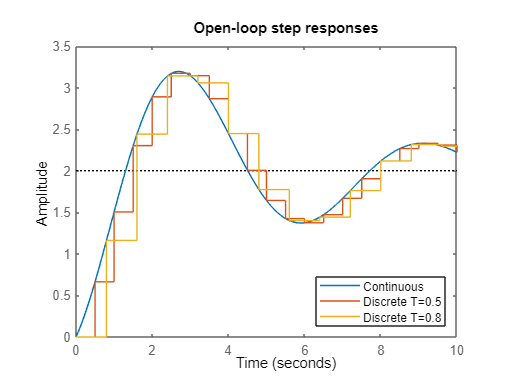

G = tf([1 2],[1 0.4 1]);  % continuous time model
T  = 0.5;              % sampling time
Gd = c2d(G,T,'zoh');    % discrete model
T2  = 0.8;             % sampling time
Gd2 = c2d(G,T2,'zoh');  % discrete model
figure; clf
step(G,Gd,Gd2,10)
legend('Continuous','Discrete T=0.5','Discrete T=0.8','Location','southeast')
title('Open-loop step responses')

#### 4.2 Closed-loop transfer functions and behaviour

Here we illustrate the computation of closed-loop transfer functions, and also how the process of discretisation means that the closed-loop behaviour does not match and changes with sampling time.  In general damping gets worse as sample time increases because the discrete case includes a ZOH and other mapping affects.

More discussion of some of these aspects is in the file ***discretisation_and_bode.mlx***.

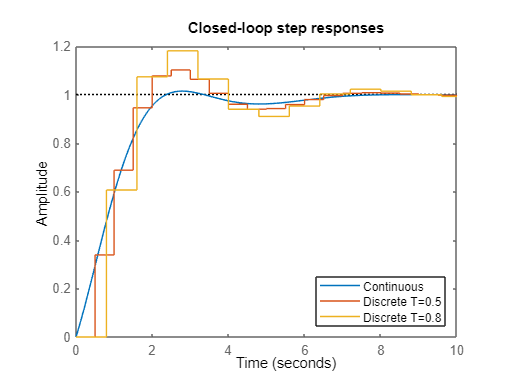

G = tf([1 2],[1 1.4 1]);  % continuous time models
M = tf([0.5 0.5],[1 0]);
T  = 0.5;              % sampling time
Gd = c2d(G,T,'zoh');    % discrete models
Md = c2d(M,T,'tustin');
T2  = 0.8;             % sampling time
Gd2 = c2d(G,T2,'zoh');  % discrete models
Md2 = c2d(M,T2,'tustin');


figure; clf
step(feedback(G*M,1),feedback(Gd*Md,1),feedback(Gd2*Md2,1),10)
legend('Continuous','Discrete T=0.5','Discrete T=0.8','Location','southeast')
title('Closed-loop step responses')